Problem1

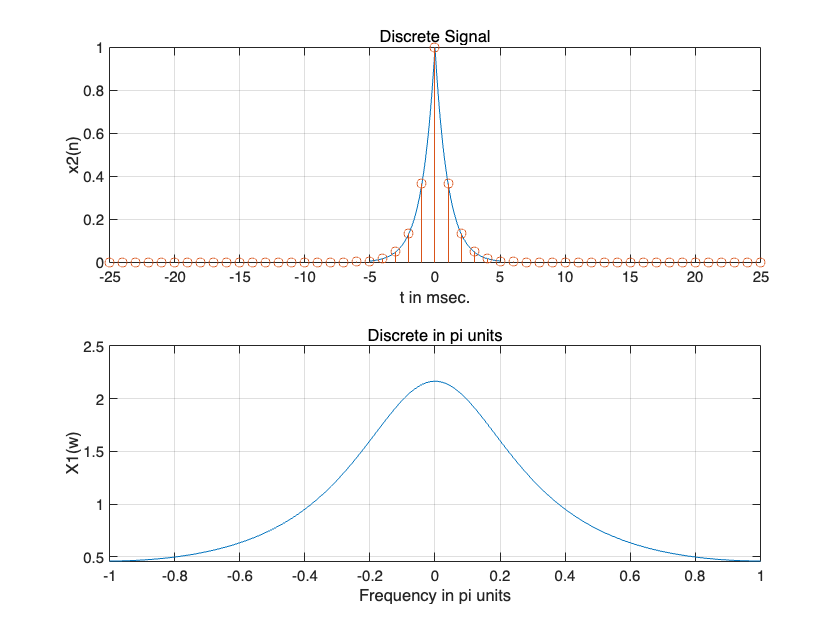

clc; clear; close all;
Dt = 0.00005;   %문제 조건 적기
t = -0.005:Dt:0.005;
xa = exp(-1000*abs(t));
%xa 샘플링
Fs = 1000; Ts = 1/Fs; n = -25:1:25; nTs = n * Ts;
x = exp(-1000*abs(nTs)); % 샘플링
%% DTFT 계산
K = 500; k = -K:1:K;
w = pi * k / K;
X = x * exp(-1j * n' * w); % DTFT
X = real(X); %실수

%시각화
figure;
subplot(2,1,1); plot(t*1000, xa); grid on;
title('Discrete Signal');
xlabel('t in msec.'); ylabel('x2(n)'); hold on;
stem(n*Ts*1000,x);
subplot(2,1,2); plot(w/pi, X); title('Discrete in pi units');
xlabel('Frequency in pi units'); ylabel('X1(w)'); grid on;

Reconstruction

%Sinc function
Dt = 0.00005;
t = -0.005:Dt:0.005;
xa_sinc = x * sinc(Fs * (ones(length(nTs),1)*t - nTs'*ones(1,length(t))));
figure; subplot(3,1,1); plot(t * 1000, xa_sinc, 'b');
xlabel('t in msec'); ylabel('xa(t)');
title('Reconstructed signal from x2(n) using sinc function'); grid on;
hold on; stem(n*Ts * 1000, x, 'r');
%Zero-Order Hold
subplot(3,1,2); stairs(nTs * 1000, x);
xlabel('t in msec'); ylabel('xa(t)');
title('Zero-Order Hold Reconstruction'); grid on;
hold on; stem(nTs * 1000, x, 'r');

%First-Order Hold
subplot(3,1,3); plot(nTs * 1000, x, '-o');
xlabel('t in msec'); ylabel('xa(t)');
title('First-Order Hold Reconstruction'); grid on;
hold on; stem(nTs * 1000, x, 'r');

Problem2

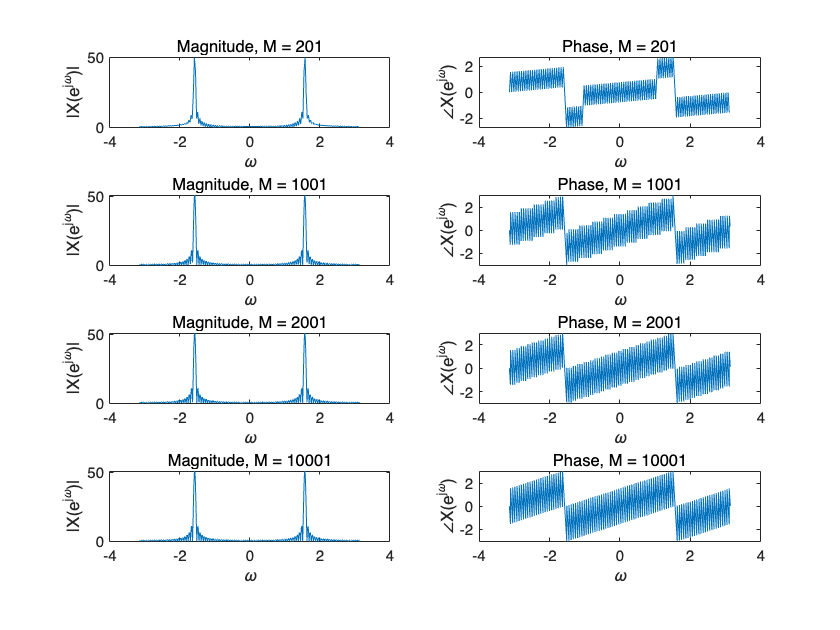

Dt = 0.00005;

t = -0.005:Dt:0.005;
xa = exp(-1000 * abs(t));
% 샘플링 주기 두 개
Ts1 = 0.0002; Fs1 = 1/Ts1; n1 = -25:1:25; nTs1 = n1 * Ts1;
Ts2 = 0.0005; Fs2 = 1/Ts2; n2 = -10:1:10; nTs2 = n2 * Ts2;
% 샘플링 신호
x1 = exp(-1000 * abs(n1*Ts1));
x2 = exp(-1000 * abs(n2*Ts2));
% DTFT
K = 500; k = -K:1:K;
w = pi * k / K;
X1 = x1 * exp(-1j * n1' * w); % Ts1
X2 = x2 * exp(-1j * n2' * w); % Ts2
% 샘플링 신호 시각화
figure;
subplot(2,1,1);
stem(n1*Ts1 * 1000, x1, 'filled'); grid on;
xlabel('t in msec)'); ylabel('x1[n]');
subplot(2,1,2);
stem(n2*Ts2 * 1000, x2, 'filled'); grid on;
xlabel('t in msec'); ylabel('x2[n]');

% DTFT magnitude plots
figure;
subplot(2,1,1);
plot(w/pi, abs(real(X1))); grid on;
title('DTFT of x1[n]');
xlabel('Normalized Frequency (\omega / \pi)'); ylabel('|X_1(\omega)|');
subplot(2,1,2);
plot(w/pi, abs(real(X2))); grid on;
title('DTFT of x2[n]');
xlabel('Normalized Frequency (\omega / \pi)'); ylabel('|X_2(\omega)|');

T_s가 2kHz인 x2[n]의 경우, DTFT 결과에서 스펙트럼이 넓게 퍼지고 왜곡된 모습이 나타난다. 이는

원래 연속시간 신호의 고주파 성분이 Nyquist 주파수를 초과하면서 aliasing 현상이 발생했을 가능성을 보여주는

지표로 해석할 수 있다. 반면, 5kHz로 샘플링한 x1[n]에서는 스펙트럼이 잘 보존되어 aliasing이 발생하지 않은

것으로 보인다.

Problem3

Ts = 0.0002; Fs = 1 / Ts; n = -25:1:25; nTs = n * Ts;
x = exp(-1000 * abs(nTs)); % Sampled signal x[n] = exp(-1000|nTs|)
Dt = 0.00005;
t = -0.005:Dt:0.005;
xa = x * sinc(Fs * (ones(length(nTs), 1) * t - nTs' * ones(1, length(t))));
% Original analog signal for comparison
x_original = exp(-1000 * abs(t));
figure;
4
plot(t, x_original,'LineWidth', 1.5); hold on;
plot(t, xa, 'LineWidth', 1.5);
stem(n*Ts, x, 'filled'); % Discrete samples
legend('원래 신호', '복원 신호', '샘플링한 신호');
xlabel('t in sec'); ylabel('Amplitude');
grid on;

Ts=0.0002s로 얻은 이산 신호에 대해 Sinc 보간법을 적용한 결과, 재구성한 신호는원래의

아날로그 신호와 거의 일치하였다. 이로 인해 원 신호를 복원해낼 수 있음을 확인하였다.